# Homework 11 (Solution)

Math 3607

Tae Eun Kim

## Problem 1 (Optimal Step Size)

To be updated.

## Problem 2 (Airplane Velocity from Radar Readings)

To be updated.

## Problem 3 (Plots of Spectra and Pseudospectra)

First, define matrices as instructed. 

z = zeros(1,60);
AA{1} = toeplitz( [0,0,0,0,z], [0,1,1,0,z] );
AA{2} = toeplitz( [0,1,0,0,z], [0,2i,0,0,z] );
AA{3} = toeplitz( [0,2i,0,0,z], [0,0,1,0.7,z] );
AA{4} = toeplitz( [0,0,1,0,z], [0,1,0,0,z] );
AA{5} = toeplitz( [0,1,2,3,z], [0,-1,-2,0,z] );
AA{6} = toeplitz( [0,0,-4,-2i,z], [0,2i,-1,2,z] );

**Digression.**

Before we start solving the problem, let me briefly show you how `toeplitz` works. Take a look at the following simpler construction.

toeplitz([0,-1,-2,-3,-4],[0,1,2,3,4])

ans =      0     1     2     3     4
    -1     0     1     2     3
    -2    -1     0     1     2
    -3    -2    -1     0     1
    -4    -3    -2    -1     0


This matrix has a constant value on each diagonal. Precisely, on the subdiagonals, starting from the main diagonal, we have

- main diagonal: 0

- 1st subdiagonal: -1

- 2nd subdiagonal: -2

- 3rd subdiagonal: -3

- 4th subdiagonal: -4

Likewise, on the superdiagonals, starting from the main diagonal, we have

- main diagonal: 0

- 1st superdiagonal: 1

- 2nd superdiagonal: 2

- 3rd superdiagonal: 3

- 4th superdiagonal: 4

These constant values on the diagonals are fed into `toeplitz` in the form of two vectors, one after another, and their first elements must agree. This seemingly simple structure enjoys many surprising analytical properties, and conversely, Toeplitz matrices appear here and there in mathematical modelling. Let's me just say this much and get back to the main problem.

Now, before we develop a script for the entire problem, let's play with one of the 6 matrices and build up from there.

A = AA{1};
[~, D] = eig(A);

Note that I used a placeholder `[~, D] `since we do not need eigenvectors. The sole output `D` must be a diagonal matrix and its diagonal entries are eigenvalues of `A.`

diag(D)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


But wait, all its eigenvalues are 0. In other words, there is only one eigenvalue $\lambda = 0$ whose algebraic multiplicity is 64! Does it make sense? Let's peak into $A$:

A(1:10, 1:10)

ans =      0     1     1     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0


As we see, all diagonals are zeros and it is not difficult to see that the characteristic polynomial of $A$ is simply $\det(A - \lambda I) = \lambda^{64}$.

Alright, so if you plot all eigenvalues in the complex plane, you must see a single dot at the origin.

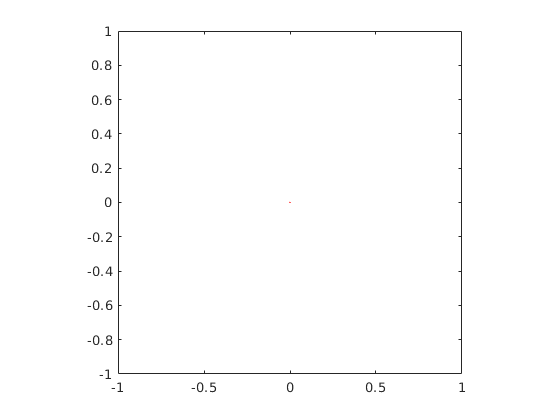

clf
plot(real(diag(D)), imag(diag(D)), 'r.', 'MarkerSize', 3)
axis image

Now, if we perturb this matrix $A$ by a random complex matrix, all these 64 eigenvalues concentrated at the origin must be scattered. Let's see how these eigenvalues are perturbed in the complex plane.

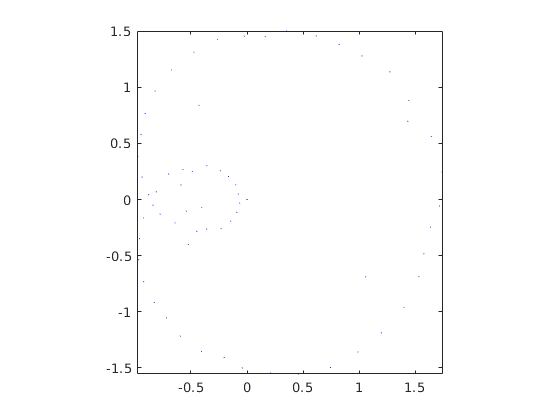

E = randn(64);
F = randn(64);
[~, Dp] = eig(A+1e-3*(E+1i*F));
hold on
plot(real(Dp), imag(Dp), 'b.', 'MarkerSize', 1)
axis image

It appears that the eigenvalues are getting spread out in some pattern. Run this block multiple times and see that it traces out a Limacon with a loop. 

Now that we have a clear idea of what the problem is asking us to do, let's write a neat script that goes through all parts with all six matrices and produces a nice plot.

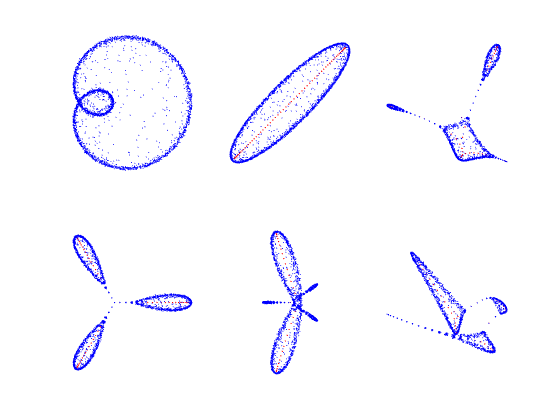

clf
for j = 1:length(AA)
    A = AA{j};
    [~,D] = eig(A);
    subplot(2,3,j)
    plot(real(D), imag(D), 'r.', 'MarkerSize', 3)
    hold on
    for i = 1:50
        E = randn(64);
        F = randn(64);
        [Vp, Dp] = eig(A+1e-3*E+1i*1e-3*F);
        plot(real(Dp), imag(Dp), 'b.', 'MarkerSize', 1)
    end
    axis image, axis off
end

## Problem 2 (SVD)

We have been playing with Vandermonde matrices several times in this semester. 

x = linspace(0,1,1000)';
A = x.^(0:999);

This is certainly an overkill for this problem, but a 1000-by-1000 matrix is not big of a deal on modern machines. 

(a) Let's print out singular values of $A_1, A_2$, and $A_3$. Just as in the previous problem, we only need singular values, which are the diagonal entries of  in the SVD . So I will use placeholders ~ to prevent `svd` from outputing `U `and `V`. In addition, I will use the economy SVD to trim extra fat off from `S` matrix.

First, $A_1$ is a single column vector and it has only one singular value.

[~,S,~] = svd(A(:,1), 0);
diag(S)

ans = 31.6228

The matrix $A_2$ consists of the first two columns of $A$ and so it has two singular values.

[~,S,~] = svd(A(:,1:2), 0);
diag(S)'

ans =    35.6038    8.1161


The matrix $A_3$ has three singular values.

[~,S,~] = svd(A(:,1:3), 0);
diag(S)'

ans =    37.5306   11.0704    1.6426


Let's use a loop to put the code into a nice script. I will use `fprintf `to format the outputs nicely for those who are familiar with it.

fmt = {'%5d', '%10.4f'};
for n = 1:3
    if n == 1
        fprintf('%5s %32s\n', 'n', 'singular values');
    end
    [~,S,~] = svd(A(:,1:n), 0);
    fprintf([fmt{[1 2*ones(1,n)]}, '\n'], n, diag(S)')
end

    n                  singular values


    1   31.6228
    2   35.6038    8.1161
    3   37.5306   11.0704    1.6426


(b) For $A_{25}$, we need to plot the singular values on a semi-log plot. Since we are plotting only a couple dozen discrete values, it makes sense to plot them in dots or circles, rather than connecting them using a line. 

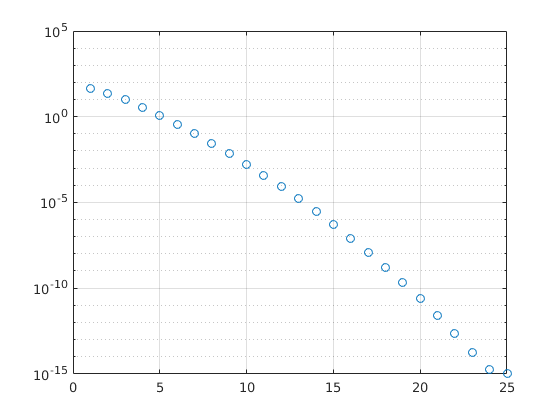

n = 25;
[~,S,~] = svd(A(:,1:n),0);
clf
semilogy(1:n, diag(S), 'o')
grid on

As we know from the theory of SVD, the singular values are arranged in descending order!

(c) In addition, we note from the previous plot that all singular values are non-negative. So, theoretically, the rank of $A_{25}$ is 25, the number of nonzero singular values. However, MATLAB gives me a different answer:

A25 = A(:,1:25);
rank(A25)

ans = 20

What is going on? As the problem instructs, let's dig into the help document for `rank`:

help rank

 rank   Matrix rank.
    rank(A) provides an estimate of the number of linearly
    independent rows or columns of a matrix A.
 
    rank(A,TOL) is the number of singular values of A
    that are larger than TOL. By default, TOL = max(size(A)) * eps(norm(A)).
 
    Class support for input A:
       float: double, single

    Documentation for rank
    Other functions named rank



The second paragraph says that the tolerance (TOL) is set to be the larger of the dimensions of the given matrix (in our case, 25) multiplied by a variant of the machine epsilon. In our case, this default tolerance is about $7\times 10^{-12}$. 

tol = max(size(A25)) * eps(norm(A25))

tol = 7.1054e-12

This means that any singular values below this level is considered as zero taking into account the artifact of floating-point arithmetic. Let's confirm that this is indeed the case using logicals.

length( find(diag(S)>tol) )

ans = 20

Bingo!

Unless you absolutely know what you are doing, I would not recommend modifying the tolerance level. But if you wish, we can do something like:

rank(A25, 1e-16)

ans = 25

## Problem 3 (SVD and 2-Norm)

(a) Since 

$\Vert A \Vert_2 = \max_{\Vert \mathbf{x} \Vert_2 = 1} \Vert A \mathbf{x} \Vert_2$, 

the technique of Lagrange multiplier from Calc 3 is very relevant. Since a norm is maximized when its square is maximized, we need to solve the following *contrained optimization problem*:

- objective function (function to be maximized): $g(\mathbf{x}) := \Vert A\mathbf{x} \Vert_2^2 = \mathbf{x}^* A^* A \mathbf{x}$;

- constraint (restriction on independen variable): $h(\mathbf{x}) := \Vert \mathbf{x} \Vert_2^2 = \mathbf{x}^* \mathbf{x} = 1$.

By Lagrange, we set the gradient of one function to be a scalar multiple of the other, 

$\nabla g(\mathbf{x}) = \lambda \nabla h(\mathbf{x})$,

and that already looks very promising due to the visual similarity to the eigenvalue problem. Furthermore, if you let $B = A^*A$, which appears in the definition of $g$, you realize that $B$ is hermitian because $B^* = B$. Therefore, according to the hint (which can be confirmed by calculus with ease), 

$\nabla g (\mathbf{x}) = 2 B \mathbf{x}$.

On the other hand, 

$\nabla h(\mathbf{x}) = \nabla (x_1^2 + x_2^2 + \cdots + x_n^2) = \langle 2x_1, 2x_2, \cdots, 2x_n \rangle = 2 \mathbf{x}$.

So, upon cancellation, the Lagrange condition implies that

$B \mathbf{x} = \lambda \mathbf{x}$,

that is, $\mathbf{x}$ must be an eigenvector of $B = A^* A$. 

(b) Now, let $\lambda_1, \ldots, \lambda_n$ be eigenvalues of $B = A^*A \in \mathbb{C}^{n \times n}$, sorted in descending order, and let $\mathbf{x}_1, \ldots, \mathbf{x}_n$ be corresponding eigenvectors, all normalized to the unit length. Then, 


$$\mathbf{x}_j^* B \mathbf{x}_j = \mathbf{x}_j^* \lambda_j \mathbf{x}_j = \lambda_j \mathbf{x}_j^* \mathbf{x}_j = \lambda_j$$


because $\mathbf{x}_j$ is a unit vector. It follows from the previous part that

$\Vert A \Vert_2^2 = \max_{\Vert \mathbf{x} \Vert_2 = 1} \Vert A \mathbf{x} \Vert_2^2 =  \max_{1 \le j \le n} \mathbf{x}_j^* B \mathbf{x}_j = \max_{1 \le j \le n} \lambda_j = \lambda_1$, 

and so $\Vert A \Vert_2 = \sqrt{\lambda_1} =: \sigma_1$, the largest singular value of $A$, which completes the proof. 

**Note.** The reaon why we were able to sort $\lambda$'s in descending magnitude is due to the fact that the eigenvalues of any hermitian matrix are always real numbers. This is by the celebrated *spectral theorem* from linear algebra. Furthermore, since the hermitian matrix $B$ is in a very special form $B = A^* A$, its eigenvalues are ensured to be not just real, but also nonnegative. This ensures that the square root of $\lambda_j$, namely, the singular value $\sigma_j$ of $A$, is real as well; by choosing the positive square root, we are fully compliant to the conventions for SVD! 